clear;
clear all;
clc;

Entrega 1 - PMR3523 Controle Moderno

Linearização

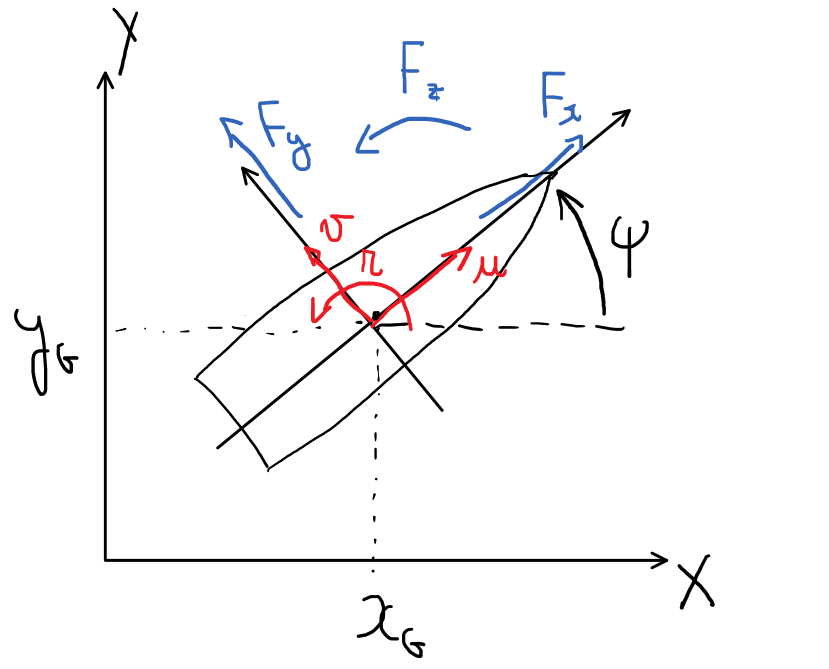

As equações utilizadas são:

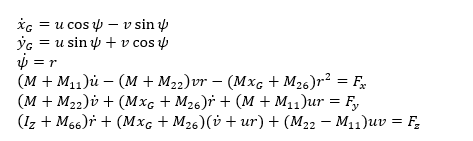      

Sendo as variáveis:

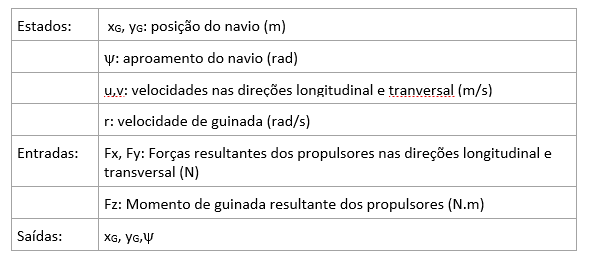


$$\begin{array}{l}
x={\left\lbrack \begin{array}{cccccc}
x_g  & y_g  & \psi \; & u & v & r
\end{array}\right\rbrack }^T \\
u={\left\lbrack \begin{array}{ccc}
F_x  & F_y  & F_z 
\end{array}\right\rbrack }^T \\
y=\left\lbrack \begin{array}{ccc}
x_g  & y_g  & \psi \;
\end{array}\right\rbrack 
\end{array}$$


Considerando os parâmetros do navio de suporte à plataforma Maersk Handler:  

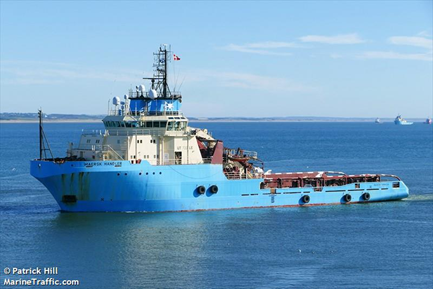        

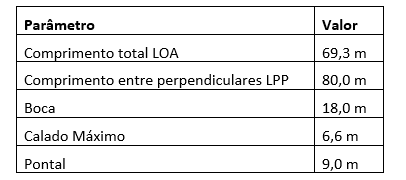

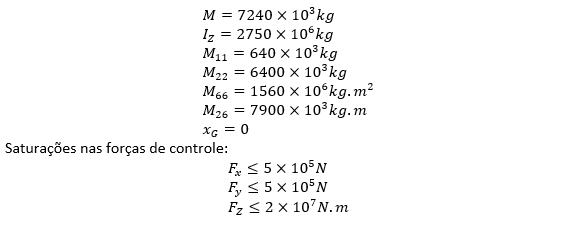

m = 7240e3;
izz = 2750e6;
m11 = 640e3;
m22 = 6400e3;
m66 = 1560e6;
m26 = 7900e3;

E as condições de linearização:

syms xg psi u v r Fx Fy Fz v_dot_lin r_dot_lin

xg_dot = u*cos(psi) - v*sin(psi)

$$xg\_dot = u\,\cos\left(\psi \right)-v\,\sin\left(\psi \right)$$

yg_dot = u*sin(psi) - v*cos(psi)

$$yg\_dot = u\,\sin\left(\psi \right)-v\,\cos\left(\psi \right)$$

psi_dot = r

$$psi\_dot = r$$

u_dot = (Fx + (m*xg + m26)*r^2 + (m + m22)*v*r)/(m+m11)

$$u\_dot = \frac{\mathrm{Fx}}{7880000}+\frac{341\,r\,v}{197}+\frac{r^{2}\,\left(7240000\,\mathrm{xg}+7900000\right)}{7880000}$$

v_dot = (Fy -(m*xg + m26)*r_dot_lin - (m + m11)*u*r)/(m+m22)

$$v\_dot = \frac{\mathrm{Fy}}{13640000}-\frac{{\dot{r}}_{\mathrm{lin}}\,\left(7240000\,\mathrm{xg}+7900000\right)}{13640000}-\frac{197\,r\,u}{341}$$

r_dot = (Fz - (m*xg + m26)*(v_dot_lin + u*r) - (m22 - m11)*u*v)/(izz + m66)

$$r\_dot = \frac{\mathrm{Fz}}{4310000000}-\frac{72\,u\,v}{53875}-\frac{\left({\dot{v}}_{\mathrm{lin}}+r\,u\right)\,\left(7240000\,\mathrm{xg}+7900000\right)}{4310000000}$$

Linearizando as equações:

lin_xg_dot = taylor(xg_dot, [u, v, psi], 0 , 'Order', 2)

$$lin\_xg\_dot = u$$


lin_yg_dot = taylor(yg_dot, [u, v, psi], 0 , 'Order', 2)

$$lin\_yg\_dot = -v$$


lin_psi_dot = taylor(psi_dot, r , 0 , 'Order', 2)

$$lin\_psi\_dot = r$$


lin_u_dot = taylor(u_dot, [xg, r, v, Fx], 0 , 'Order', 2)

$$lin\_u\_dot = \frac{\mathrm{Fx}}{7880000}$$

A = 1.2690e-07


lin_v_dot = taylor(v_dot, [xg, r_dot_lin, u, r, Fy], 0 , 'Order', 2)

$$lin\_v\_dot = \frac{\mathrm{Fy}}{13640000}-\frac{395\,{\dot{r}}_{\mathrm{lin}}}{682}$$


lin_r_dot = taylor(r_dot, [xg, v_dot_lin, u, r, v, Fz], 0 , 'Order', 2)

$$lin\_r\_dot = \frac{\mathrm{Fz}}{4310000000}-\frac{79\,{\dot{v}}_{\mathrm{lin}}}{43100}$$

Substituindo o termo $\dot{\;r_{\textrm{lin}} }$ no termo $\dot{\;v_{\textrm{lin}} }$, tem-se:


$$\dot{\;v_{\textrm{lin}} } =\frac{\;F_y }{13640000}-\frac{395}{682}\left(\frac{\;F_z }{4310000000}-\frac{79}{43100}\dot{\;v_{\textrm{lin}} } \right)$$


a= 395/682;
b = 79/43100;
c = a*b

c = 0.0011

d = a/4310000000

d = 1.3438e-10


$$\dot{\;v_{\textrm{lin}} } -0,0011\dot{\;v_{\textrm{lin}} } =\frac{\;F_y }{13640000}-d*F_z$$


e = 1/(13640000*0.9989)

e = 7.3395e-08

f = d/0.9989

f = 1.3453e-10


$$\dot{\;v_{\textrm{lin}} } =e*F_y -f*F_z$$


Fazendo a substituição do termo $\dot{\;v_{\textrm{lin}} }$ no termo $\dot{\;r_{\textrm{lin}} }$ tem-se:


$$\dot{\;r_{\textrm{lin}} } =\frac{F_z }{4310000000}-\frac{\;79}{43100}\left(e*F_y -f*F_z \right)$$


g = (79/43100)*e

g = 1.3453e-10

h = (79/43100)*f

h = 2.4658e-13

i = (1/4310000000)+h

i = 2.3227e-10


$$\dot{\;r_{\textrm{lin}} } =-g*F_y \;+\;i*F_z$$


Colocando os termos na forma matricial do espaço de estados:


$$\begin{array}{l}
\delta \dot{x} =A\delta x\left(t\right)+B\delta u\left(t\right)\\
\;\delta y=C\delta x\left(t\right)+D\delta u\left(t\right)\;
\end{array}$$



$$A=\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & -1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$
 
$$B=\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0\\
1,269*{10}^{-7}  & 0 & 0\\
0 & e & -f\\
0 & -g & i
\end{array}\right\rbrack$$
 
$$C=\left\lbrack \begin{array}{cccccc}
1 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0
\end{array}\right\rbrack$$
 
$$D=\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack$$


Definindo as características do modelo:

A = [0 0 0 1 0 0
     0 0 0 0 -1 0
     0 0 0 0 0 1
     0 0 0 0 0 0
     0 0 0 0 0 0
     0 0 0 0 0 0];
 
B = [0 0 0 
    0 0 0
    0 0 0
    1.269e-07 0 0
    0 e -f
    0 -g i];

C = [1 0 0 0 0 0
    0 1 0 0 0 0
    0 0 1 0 0 0];

D = 0;

Informações para a simulação:

t = 0:0.01:10;
u = zeros(length(t),3); %vetor de entrada do nosso modelo
x0 = [0 0 0 0 0 0]; %Condição inicial do nosso modelo

Estabilidade:

poles = eig(A)

poles =      0
     0
     0
     0
     0
     0


Simulação:

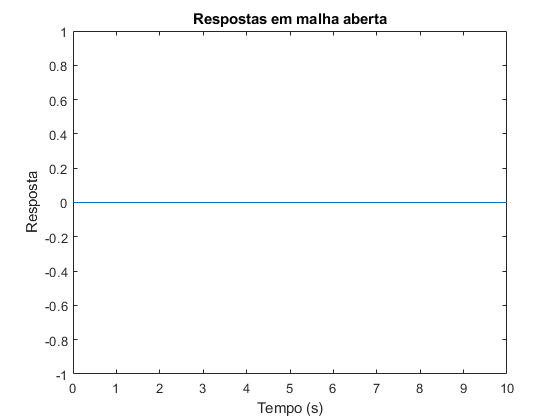

sys = ss(A,B,C,D);
[y,T,x] = lsim(sys,u,t,x0);
plot(T,y(:,2))
title('Respostas em malha aberta')
xlabel('Tempo (s)')
ylabel('Resposta')